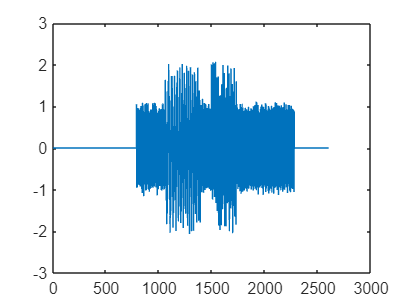

clear
clc

fs = 1e8;
num_signal = 3;
t = 0:1/fs:(26e-6); %时间序列 26us
x = complex(zeros(1,length(t))); %空采样序列
SNR = rand(1,num_signal)*10 + 10; %SNR in [10,20]dB
f0 = (rand(1,num_signal)*21+2)*1e6; %f0 in [2e6,23e6]Hz
f1 = (rand(1,num_signal)*21+2)*1e6; %f1 in [2e6,23e6]Hz
B = f1 - f0;
T = (rand(1,num_signal)*5+5)*(1e-6); %持续时间5~10us
t0 = 1.5*rand(1,num_signal)*(1e-5); %开始时间0~15us
real_fm = (f1-f0)./T;
real_fh = (f1+f0)/2;

for i = 1:num_signal
    chrp = my_chirp(T(i),f0(i),f1(i),fs); %生成chirp信号
    % plot(1:length(chrp),chrp);
    chrp = awgn(chrp,20);
    n0 = floor(t0(i) * fs) + 1; %计算开始时间采样点序号
    n1 = n0 + length(chrp)-1;
    x(n0:n1) = x(n0:n1)+chrp;
end

plot(real(x));

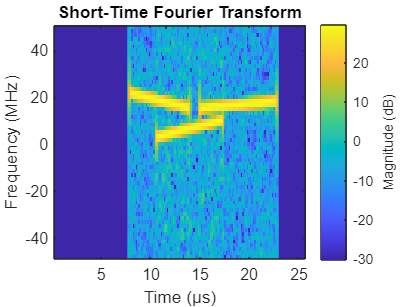

stft(x,fs,"Window",hann(60,'periodic'));

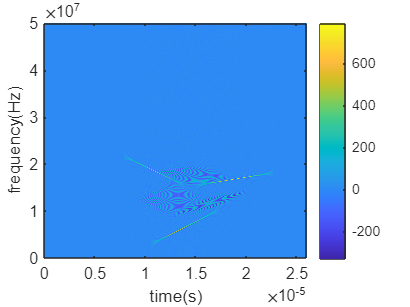


[d,f,t] = wvd(x,fs);
imagesc(t,f,d)
axis xy
xlabel('time(s)')
ylabel('frequency(Hz)')
colorbar

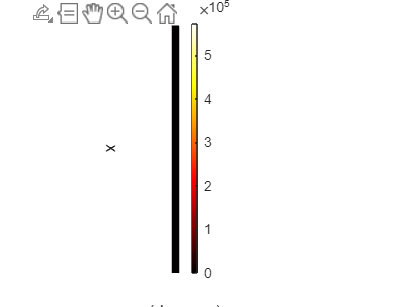


theta = 1:0.5:179;
[R,xp] = radon(d,theta);
R(R<(0.9*max(R))) = 0;
imshow(R,[],'Xdata',theta,'Ydata',xp,'InitialMagnification','fit')
xlabel('\theta (degrees)')
ylabel('x')
colormap(gca,hot), colorbar